# MATLAB で Audio Plugin 開発

**# 03 ディストーション**

松本 和樹 (早稲田大学，MATLAB Student Ambassador)

## ディストーション

freq    =880;
preGain =25.691;
b       =0;
  
fs = 16000;                 % サンプリング周波数を指定
t  = (0:4095)'/fs;          % 時間ベクトルの作成

F = @(x) min(max(x,-1),1);  % ハードクリッピングの関数
x = sin(2 * pi * freq * t); % 正弦波の作成
a = db2mag(preGain);        % preGain [dB] の単位変換
y = F(a.*(x + b));          % ディストーションの適用

再生

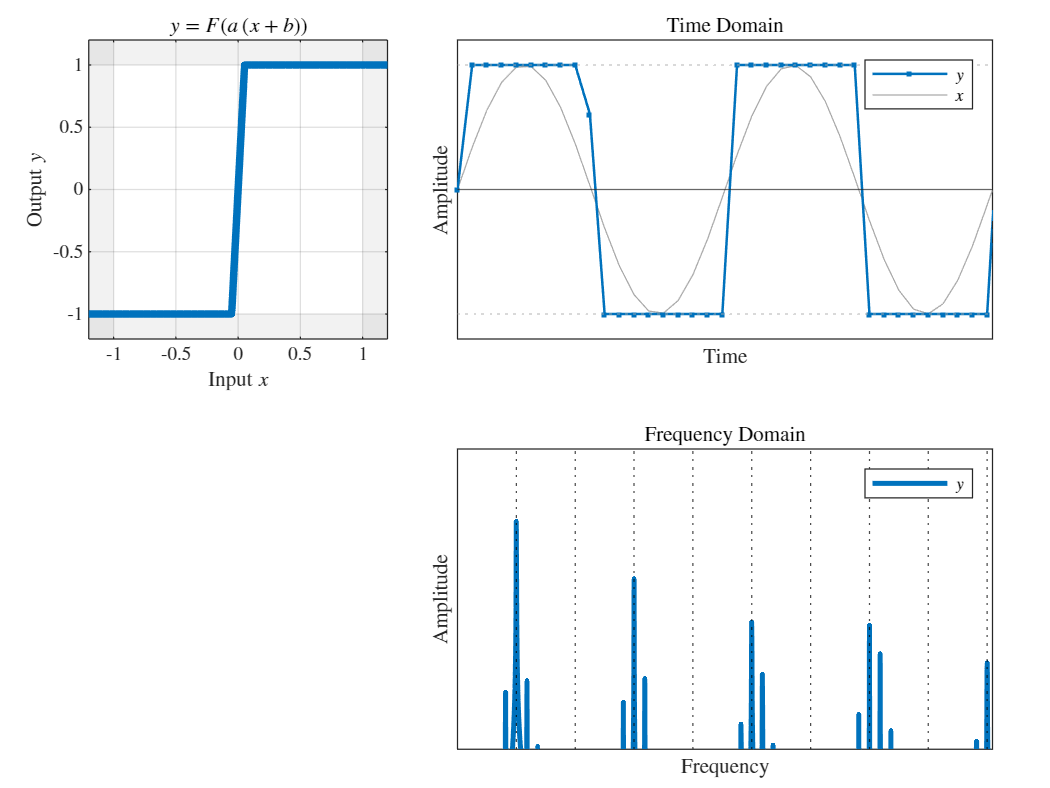

soundsc(y,16000);
figure;
visualizeDistortion(t,x,y,freq,F,a,b,fs);

## サンプリング定理

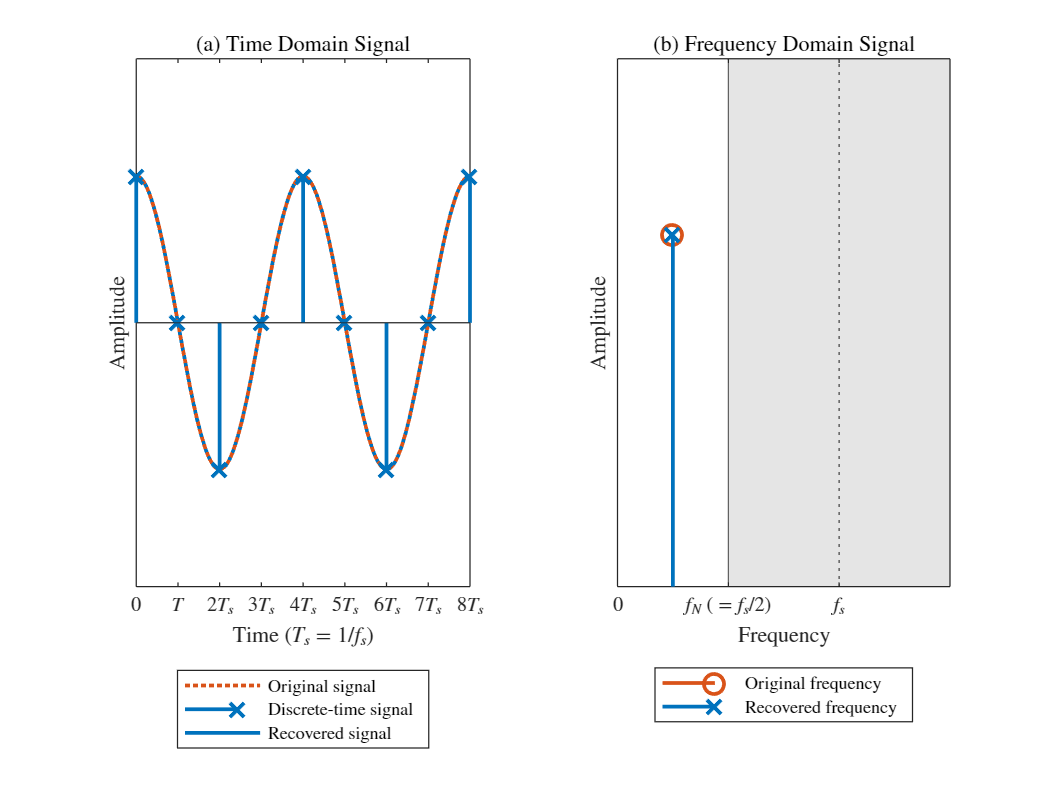

freq = 0.25;

figure; visualizeSamplingTheorem(freq);

## 矩形波のフーリエ級数展開

K = 20;

figure; visualizeSquareWave(K);

## 矩形波のアンチエイリアシング

fs = 50;

figure; visualizeAntialiasing(fs);

### オーバーサンプリングを用いたディストーション

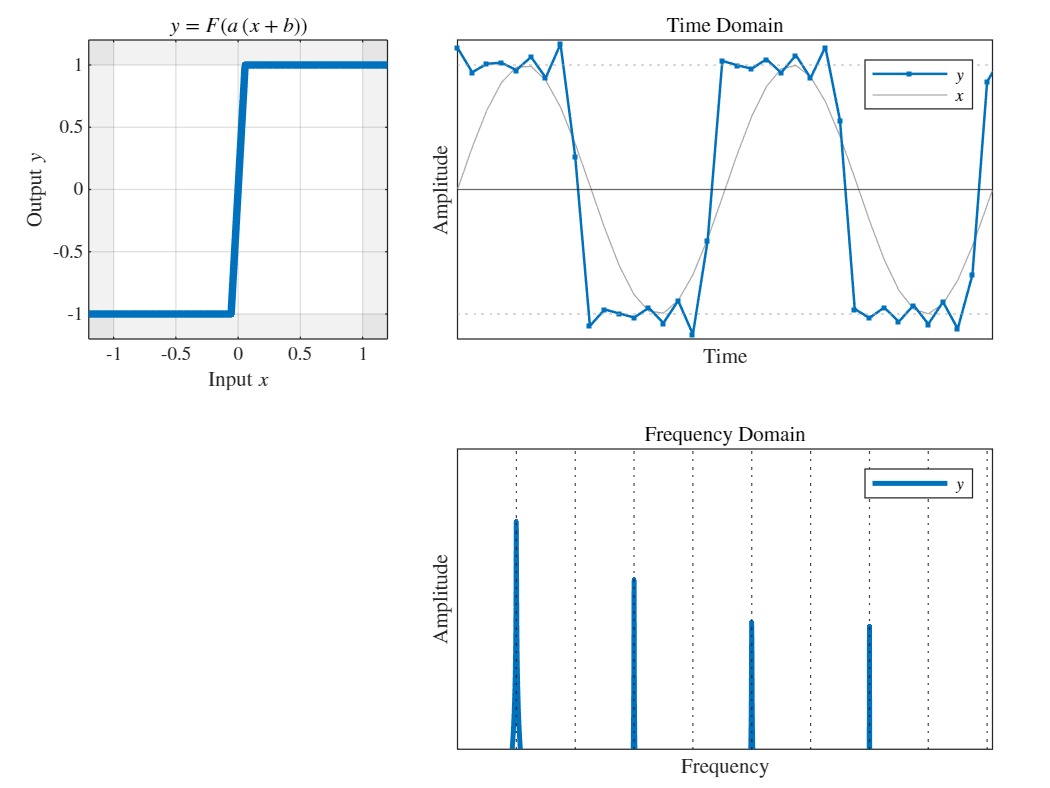

% パラメータの設定
freq    =880;
preGain =25;
b       =0;
M       =     16;

fs = 16000;                  % サンプリング周波数を指定
t  = (0:4095)'/fs;           % 時間ベクトルの作成
x  = sin(2 * pi * freq * t); % 正弦波の作成
a  = db2mag(preGain);        % デシベル値から係数 a を計算
f  = @(x) min(max(x,-1),1);  % ハードクリッピングの関数

x2 = interp(x,M);            % アップサンプリング
y2 = f(a.*(x2 + b));         % ディストーションの適用
y  = decimate(y2,M);         % ダウンサンプリング

% 結果の確認
soundsc(y,16000); 
visualizeDistortion(t,x,y,freq,F,a,b,fs);

## プラグインのテスト・検証・生成

audioTestBench('MATLAB_Distortion')

validateAudioPlugin('MATLAB_Distortion')

 generateAudioPlugin('MATLAB_Distortion')

#### スライド用

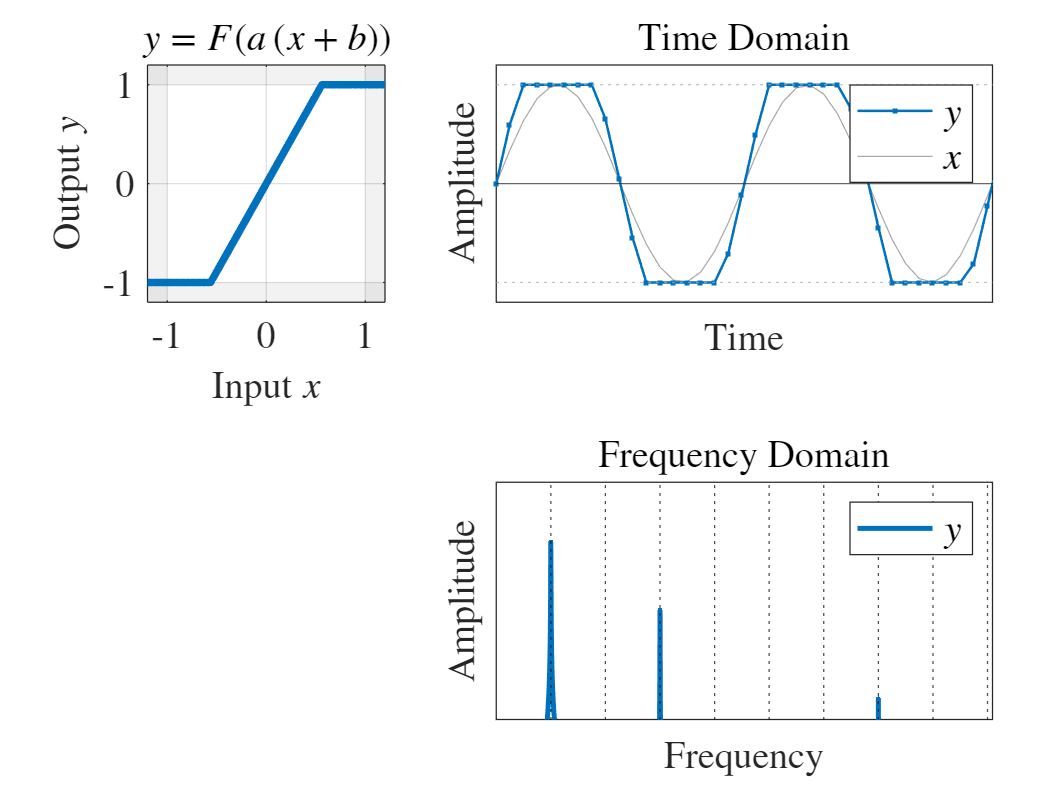

freq = 880;
b    = 0;
fs   = 16000;                 % サンプリング周波数を指定
t    = (0:4095)'/fs;          % 時間ベクトルの作成
f    = @(x) min(max(x,-1),1);  % Hard Clipping の関数
x    = sin(2 * pi * freq * t); % 正弦波の作成

figure;
preGain = 5;
a = db2mag(preGain);        % preGain [dB] の単位変換
y = f(a.*(x + b));          % ディストーションの適用
visualizeDistortion(t,x,y,freq,F,a,b,fs);

fontsize(15,"points"); print("docs/assets/images/03/note3_naive_distortoin_5.svg",'-dsvg'); % スライド作成用

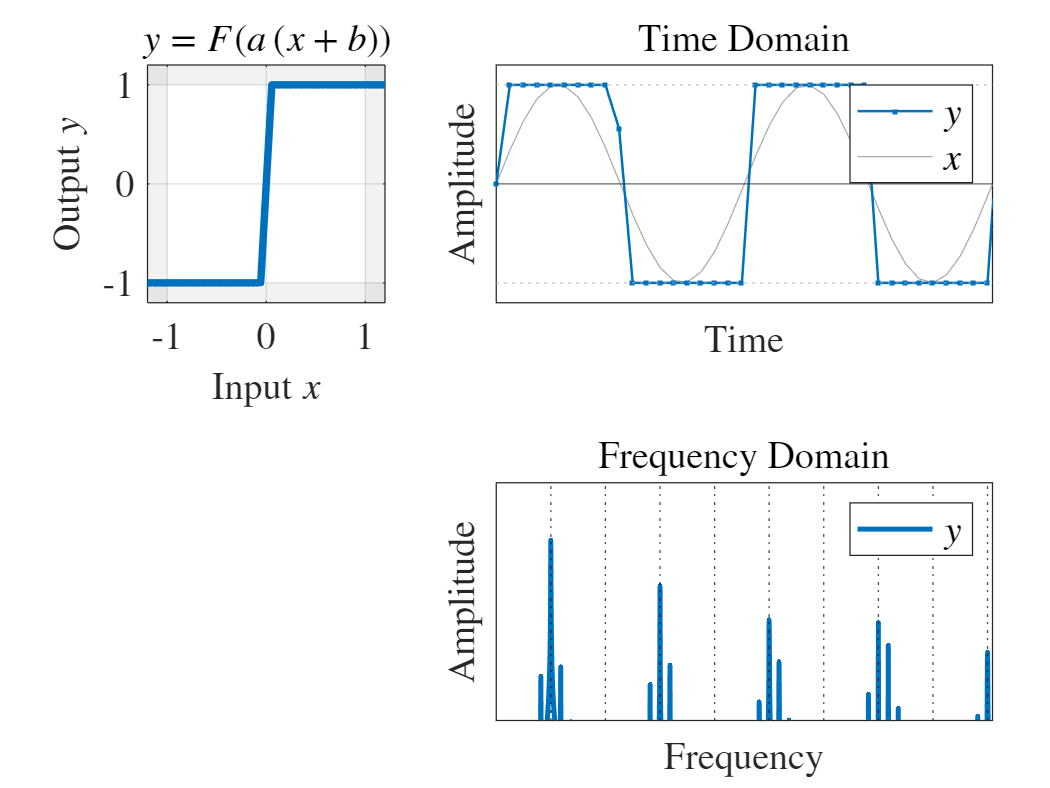

preGain = 25;
a = db2mag(preGain);        % preGain [dB] の単位変換
y = f(a.*(x + b));          % ディストーションの適用
visualizeDistortion(t,x,y,freq,F,a,b,fs);
fontsize(15,"points"); print("docs/assets/images/03/note3_naive_distortoin_25.svg",'-dsvg'); % スライド作成用

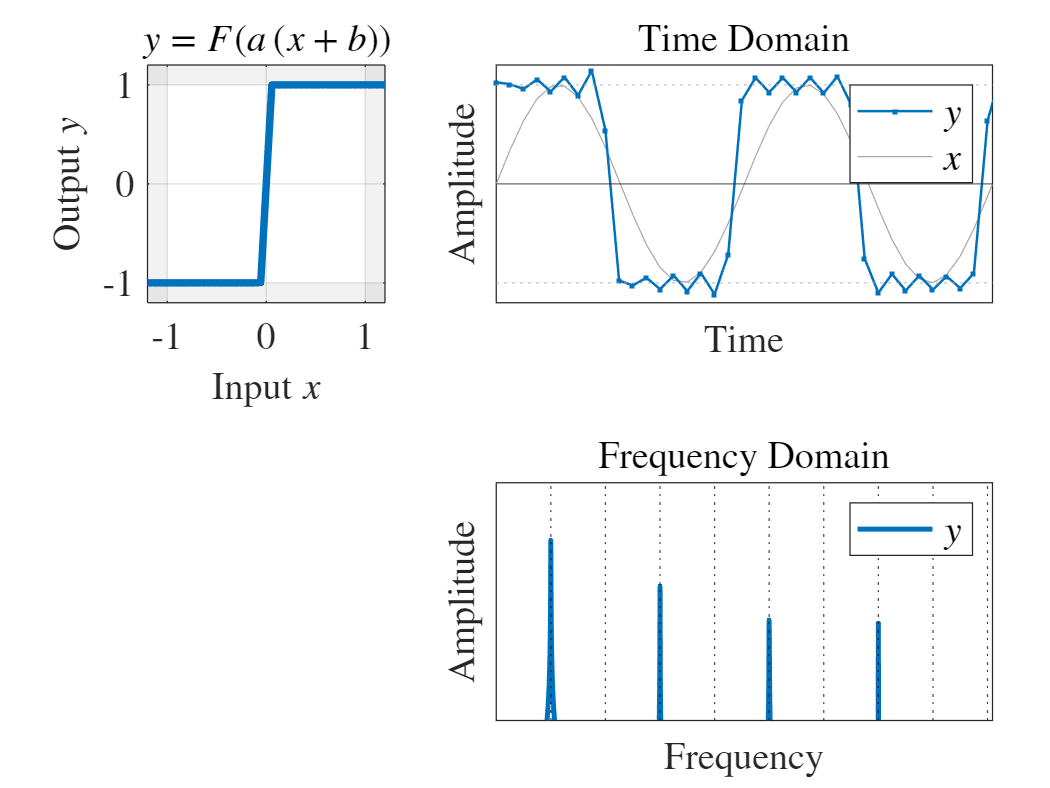


M  = 4;
x2 = interp(x,M);            % アップサンプリング
y2 = f(a.*(x2 + b));         % ディストーションの適用
y  = decimate(y2,M);         % ダウンサンプリング
visualizeDistortion(t,x,y,freq,F,a,b,fs);
fontsize(15,"points"); print("docs/assets/images/03/note3_naive_distortoin_25_oversampling.svg",'-dsvg'); % スライド作成用

videoFile = 'docs/assets/images/03/sampling_theorem_visualization.mp4';
v = VideoWriter(videoFile, 'MPEG-4');
v.FrameRate = 60;
v.Quality = 100;
open(v);


for freq = linspace(0, 1.5, 180) 
    visualizeSamplingTheorem(freq);
    fontsize(10,"points")
    drawnow;
    exportgraphics(fig, 'temp.png', 'Resolution', 600); 
    frame = imread('temp.png');
    writeVideo(v, im2frame(frame));
end
close(v);

videoFile = 'docs/assets/images/03/square.mp4';
v = VideoWriter(videoFile, 'MPEG-4');
v.FrameRate = 15;
v.Quality = 100;
open(v);

for K = linspace(1,20,20) 
    visualizeSquareWave(K);
    fontsize(10,"points")
    drawnow;
    exportgraphics(gcf, 'temp.png', 'Resolution', 600); 
    frame = imread('temp.png');
    writeVideo(v, im2frame(frame));
    close(gcf);
end
close(v);

videoFile = 'docs/assets/images/03/anti_aliasing_visualization.mp4';
v = VideoWriter(videoFile, 'MPEG-4');
v.FrameRate = 60;
v.Quality = 100;
open(v);

figure;
for fs = linspace(1,100,120)
    visualizeAntialiasing(fs);
    drawnow;
    exportgraphics(gcf, 'temp.png', 'Resolution', 600); 
    frame = imread('temp.png');
    writeVideo(v, im2frame(frame));
end
close(v);

visualizeAntialiasing(25);
print("docs/assets/images/03/anti_aliasing_visualization_poster.svg",'-dsvg');

M   = 4
figure(Position=[0,0, 400, 300]); 
visualizeDistortionWithOverSampling(M)
print("docs/assets/images/03/note3_oversampling",'-dsvg');

function setDefaultInterpreterLaTeX
defaults            = fieldnames(get(groot,"factory"));
interpreterSettings = defaults(contains(defaults,"Interpreter"));
for i = 1:numel(interpreterSettings)
    set(groot, replace(interpreterSettings{i},"factory","default"),"latex")
end
end

function resetDefaultInterpreter
defaults            = fieldnames(get(groot,"factory"));
interpreterSettings = defaults(contains(defaults,"Interpreter"));
for i = 1:numel(interpreterSettings)
    set(groot, replace(interpreterSettings{i},"factory","default"),"remove")
end
end

function visualizeDistortion(t,x,y,freq,F,a,bias,fs)
setDefaultInterpreterLaTeX;

X  = abs(fft(x,4096))/numel(x);
Y  = abs(fft(y,4096))/numel(x);
f  = (0:numel(X)-1)/numel(X) * fs;

figure;
tiledlayout(2,5,"Padding","compact");
nexttile(1,[1 2]);
fplot(@(x)F(a.*(x + bias)),LineWidth=3);
xlabel('Input $x$');
ylabel('Output $y$');
grid on;
xlim([-1.2 1.2])
ylim([-1.2 1.2])
xregion([-1.2 1],[-1 1.2],FaceColor="k",FaceAlpha=0.05);
yregion([-1.2 1],[-1 1.2],FaceColor="k",FaceAlpha=0.05);
title('$y = F(a\,(x+b))$');
axis square;

nexttile([1 3]);
hold on;
plot(t,x,Color='#AAAAAA');
plot(t,y,".-",LineWidth=1,Color='#0072BD');
xlim([0 2/freq]);
ylim([-1.2 1.2]);
xticks([]);
yticks([]);
xlabel('Time');
ylabel('Amplitude');
title('Time Domain')
yline(0);
yline([-1 1],":",Color='#AAAAAA');
box on;
l = legend('$x$','$y$'); l.Direction = 'reverse';

nexttile(8,[1 3]);
plot(f,Y,LineWidth=2,Color='#0072BD');
xlim([0 fs/2]);
xlabel('Frequency');
ylabel('Amplitude');
title('Frequency Domain')
xline(freq*(1:fs/freq),'k:');
box on;
legend('$y$');
yscale("log");
xticks([]);
yticks([]);

ylim([1e-2 2]);

% fontsize(15,"points");
resetDefaultInterpreter;
end

function visualizeSamplingTheorem(freq)
setDefaultInterpreterLaTeX;

tiledlayout(1,2);
fs       = 1;
T        = 1/fs;
len      = 8*T;
t        = 0:T:len;

waveOriginal  = @(t)cos(2*pi*freq*t);
freqRecovered = abs(freq - round(freq/fs) * fs);
waveRecovered = @(t)cos(2*pi*freqRecovered*t);

nexttile;
hold on;
rcov = fplot(waveRecovered,"-",LineWidth=1.5,DisplayName="Recovered signal");
orig = fplot(waveOriginal,":",LineWidth=1.5,DisplayName="Original signal");
samp = stem(t,waveOriginal(t),"x-",LineWidth=1.5,Color=rcov.Color,MarkerSize=8,DisplayName="Discrete-time signal");
legend([orig, samp, rcov],autoUpdate="off",Location="southoutside");
xlim([0 len]);
ylim([-1.8 1.8]);
yline(0);
ylabel("Amplitude");
yticks([]);
xlabel("Time ($T_s = 1/f_s$)")
xticks(t);
xticklabels(["$0$" "$T$", "$"+(2:10)+"T_s$"]);
xtickangle(0);
box on;
title("(a) Time Domain Signal");

nexttile
hold on
orig=stem(freq,1,"o-",LineWidth=1.5,Color=orig.Color,MarkerSize=8,DisplayName="Original frequency");
rcov=stem(freqRecovered,1,"x-",LineWidth=1.5,Color=rcov.Color,MarkerSize=8,DisplayName="Recovered frequency");
xlim([0 1.5 * fs]);
ylabel("Amplitude");
yticks([]);
xticks([0 fs/2 fs]);
xticklabels(["0","$f_N~({}=f_s / 2)$","$f_s$"]);
xlabel("Frequency")
xtickangle(0);
ylim([0 1.5]);
xline(fs/2);
xline(fs,"k:");
xregion(fs/2, 1.5*fs,FaceColor="k",FaceAlpha=0.1);
box on;
legend([orig, rcov],autoUpdate="off",Location="southoutside");
title("(b) Frequency Domain Signal");

resetDefaultInterpreter;
end

function visualizeAntialiasing(fs)
fcn = @(x) 1 * (x>=0) + -1 * (x < 0);
x   = @(t) sin(2*pi*t);
y   = @(t) fcn(x(t));
a   = @(k) (2/pi)./k;
z   = @(t,K) reshape(2*sum(sin(2*pi*(1:2:K).*t(:)).*a(1:2:K),2),size(t));
KLP = fs/2;
K   = 50;
t   = (0:1/fs:1)';
f   = 1:2:K;

setDefaultInterpreterLaTeX;
tiledlayout(2,2,TileSpacing="compact")

nexttile(1)
hold on;
fplot(y,LineWidth=1.5,Color="#D95319");
stem(t, y(t),".-",MarkerSize=8,LineWidth=1.5,Color="#0072BD");
xlim([0 1])
box on;
ylim([-1.5 1.5])
title("(a) Square wave"+newline+"(Time domain)")
xlabel("Time")
ylabel("Amplitude")

nexttile(2)
hold on;
fplot(y,LineWidth=1.5,Color="#AAAAAA")
fplot(@(t)z(t,fs/2),LineWidth=1.5,Color="#D95319")
stem(t, z(t,fs/2),".-",MarkerSize=8,LineWidth=1.5,Color="#0072BD")
xlim([0 1])
box on;
ylim([-1.5 1.5])
title("(b) Bandlimited square wave"+newline+"(Time domain)")
xlabel("Time")
ylabel("Amplitude")

nexttile(3)
hold on;
stem(f,a(f),"o-",LineWidth=1.5,Color="#D95319")
ff = 1:2:5*K;
stem(abs(ff - round(ff/fs) * fs),a(ff),".-",LineWidth=1.5,Color="#0072BD")
xlim([0 K])
ylim([1e-2 2]);
box on;
xregion([fs/2 K])
title("(c) Bandlimited square wave"+newline+"(Frequency domain)")
xlabel("Frequency")
xline(fs/2,"k-","$f_N$","LabelOrientation","horizontal",LabelHorizontalAlignment="left");
yscale("log");
ylabel("Amplitude")

lgd = legend("Continuous-time", "Descrete-time");
lgd.Layout.Tile = "south";
lgd.Orientation = "horizontal";

nexttile(4)
hold on;
stem(f,a(f),"o-",LineWidth=1.5,Color="#AAAAAA")
f = 1:2:KLP;
stem(f,a(f),"o-",LineWidth=1.5,Color="#D95319")
stem(abs(f - round(f/fs) * fs),a(f),".-",LineWidth=1.5,Color="#0072BD")
xlim([0 fs])
box on;
xregion([fs/2 K])
xlim([0 K])
ylim([1e-2 2]);
title("(d) Bandlimited square wave"+newline+"(Frequency domain)")
xlabel("Frequency")
xline(fs/2,"k-","$f_N$","LabelOrientation","horizontal",LabelHorizontalAlignment="left");
yscale("log");
ylabel("Amplitude")
end

function visualizeSquareWave(K)
t = linspace(0,1,1000);

figure("Position",[0 0 560 210]);
setDefaultInterpreterLaTeX;
tiledlayout(1,2)
nexttile(2);
y = zeros(size(t));
hold on;
for k = 1:2:K
    yk = (4/(pi*k)) * sin(2*pi*k*t);
    y  = y + yk;
    plot(t,yk,"-",Color="#AAAAAA");
end
title("Harmonic Components")
box on;
xlabel("Time");
ylabel("Amplitude");
ylim([-1.5 1.5]);

nexttile(1);
hold on
plot(t,1*(t<0.5) + -1*(t>0.5),":","Color","#0072BD","LineWidth",2); 
plot(t,y,"Color","#0072BD","LineWidth",2);                           
title("Square wave")
box on;
xlabel("Time");
ylabel("Amplitude");
ylim([-1.5 1.5]);
end

function visualizeDistortionWithOverSampling(M)
setDefaultInterpreterLaTeX;
fs  = 12;
f   = @(x) 1*(x>0) + -1*(x<0);
z   = @(t,K) reshape(4/pi*sum(sin(2*pi*(1:2:K).*t(:))./(1:2:K),2),size(t));
t   = 0:1/fs:1-1/fs;
tus = 0:1/fs/M:1-1/fs/M;

x   = sin(2*pi*t);
xus = resample(x,M,1);
yus = f(xus);
y   = resample(yus,1,M);

tiledlayout(2,3,TileSpacing="loose",Padding="compact")
t1 = nexttile(1); fplot(@(t)sin(2*pi*t),    Color="#AAAAAA",LineWidth=2); hold on; stem(t  ,x              ,".-",Color="#0072BD"); xlim([0 1]); title ("Input");               xticks([]); yticks([]); ylim([-1.2 1.2]); ylabel("Sample Rate ${}=f_s$"+newline);   
t2 = nexttile(4); fplot(@(t)sin(2*pi*t),    Color="#AAAAAA",LineWidth=2); hold on; stem(tus,xus            ,".-",Color="#0072BD"); xlim([0 1]); xlabel("Upsampled");           xticks([]); yticks([]); ylim([-1.2 1.2]); ylabel("Sample Rate ${}=M\,f_s$"+newline); set(gca,"Color","#EEEEEE")
t3 = nexttile(5); fplot(@(t)f(sin(2*pi*t)), Color="#AAAAAA",LineWidth=2); hold on; stem(tus,yus            ,".-",Color="#0072BD"); xlim([0 1]); xlabel("Distorted");           xticks([]); yticks([]); ylim([-1.2 1.2]);                                            set(gca,"Color","#EEEEEE")
t4 = nexttile(6); fplot(@(t)z(t,fs/2),      Color="#AAAAAA",LineWidth=2); hold on; stem(tus,resample(y,M,1),".-",Color="#0072BD"); xlim([0 1]); xlabel("After Anti-aliasing"); xticks([]); yticks([]); ylim([-1.2 1.2]);                                            set(gca,"Color","#EEEEEE")
t5 = nexttile(3); fplot(@(t)z(t,fs/2),      Color="#AAAAAA",LineWidth=2); hold on; stem(t  ,y              ,".-",Color="#0072BD"); xlim([0 1]); title ("Output");              xticks([]); yticks([]); ylim([-1.2 1.2]);                                           
                                          
lgd = legend("Continuous-time signal","Descrete-time signal");
lgd.Layout.Tile = "south";
lgd.Orientation = "horizontal";

addoperatorH = @(left,right,text,fontsize) annotation("textbox",...
                                [left.Position(1)+left.Position(3) ...
                                 left.Position(2) ...
                                 right.Position(1) - (left.Position(3) + left.Position(1)) ...
                                 left.Position(4)], ...
                                 "String",text, ...
                                 "FontSize", fontsize, ...
                                 HorizontalAlignment="center", ...
                                 VerticalAlignment="middle", ...
                                 EdgeColor="none", ...
                                 Interpreter="latex", ...
                                 FitBoxToText="on");

addoperatorV = @(top,bottom,text,fontsize) annotation("textbox",...
                                 [bottom.Position(1),...
                                 bottom.Position(2) + bottom.Position(4),...
                                 bottom.Position(3),...
                                 top.Position(2) - (bottom.Position(4) + bottom.Position(2)),...
                                 ], ...
                                 "String",text, ...
                                 "FontSize", fontsize, ...
                                 HorizontalAlignment="center", ...
                                 VerticalAlignment="middle", ...
                                 EdgeColor="none", ...
                                 Interpreter="latex", ...
                                 FitBoxToText="on");

addoperatorH(t2,t3,"$\rightarrow$",15)
addoperatorH(t2,t3,"$F$"+newline+newline,8)

addoperatorH(t3,t4,"$\rightarrow$",15)
addoperatorH(t3,t4,"AAF"+newline+newline,8)

% addoperatorV(t1,t2,"$\quad$",15)
addoperatorV(t1,t2,"Upsample $\downarrow$",8)

% addoperatorV(t5,t4,"$\uparrow\quad$",15)
% addoperatorV(t5,t4,"\quad\quad\qquad\qquad\  Downsample",8)
addoperatorV(t5,t4,"$\uparrow$ Downsample",8)
end